# PARTIE 1 - ECONOMETRIE

# Aurore GOSMANT & Gaspard ROBERT - Février 2020

# Question 1 :

On supprime les données où la variable wage n'est pas définie

load MROZ.raw;

# Question 2: Statistiques descriptives du salaire, de l'âge et de l'éducation

### Pour l'ensemble des femmes

[n,k] = size(MROZ)

n = 428

k = 22

wage = MROZ(:,7);
age = MROZ(:,5);
educ = MROZ(:,6);
fprintf('Wage :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(wage),std(wage),var(wage),max(wage),min(wage))

Wage :
    mean : 4.177682e+00
    standard deviation : 3.310282e+00
    variance : 1.095797e+01
    max : 25
    min : 1.282000e-01


fprintf('Age :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(age),std(age),var(age),max(age),min(age));

Age :
    mean : 4.197196e+01
    standard deviation : 7.721084e+00
    variance : 5.961514e+01
    max : 60
    min : 30


fprintf('Education :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(educ),std(educ),var(educ),max(educ),min(educ));

Education :
    mean : 1.265888e+01
    standard deviation : 2.285376e+00
    variance : 5.222942e+00
    max : 17
    min : 5


### Pour les femmes dont le salaire du mari est supérieur à la médiane de l'échantillon

HusWageMed = median(MROZ(:,12));
MROZH = MROZ((MROZ(:,12)>HusWageMed),:);
wageH = MROZH(:,7);
ageH = MROZH(:,5);
educH = MROZH(:,6);
clear std
fprintf('Wage :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(wageH),std(wageH),var(wageH),max(wageH),min(wageH));

Wage :
    mean : 4.896822e+00
    standard deviation : 4.041606e+00
    variance : 1.633458e+01
    max : 25
    min : 1.616000e-01


fprintf('Age :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(ageH),std(ageH),var(ageH),max(ageH),min(ageH));

Age :
    mean : 4.227570e+01
    standard deviation : 7.388843e+00
    variance : 5.459499e+01
    max : 59
    min : 30


fprintf('Education :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(educH),std(educH),var(educH),max(educH),min(educH));

Education :
    mean : 1.324299e+01
    standard deviation : 2.359045e+00
    variance : 5.565091e+00
    max : 17
    min : 5


## Pour les femmes dont le salaire du mari est inférieur à la médiane de l'échantillon

MROZH = MROZ((MROZ(:,12)<HusWageMed),:);
wageH = MROZH(:,7);
ageH = MROZH(:,5);
educH = MROZH(:,6);
clear std
fprintf('Wage :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(wageH),std(wageH),var(wageH),max(wageH),min(wageH));

Wage :
    mean : 3.458541e+00
    standard deviation : 2.143274e+00
    variance : 4.593623e+00
    max : 1.826700e+01
    min : 1.282000e-01


fprintf('Age :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(ageH),std(ageH),var(ageH),max(ageH),min(ageH));

Age :
    mean : 4.166822e+01
    standard deviation : 8.045482e+00
    variance : 6.472978e+01
    max : 60
    min : 30


fprintf('Education :\n    mean : %d\n    standard deviation : %d\n    variance : %d\n    max : %d\n    min : %d\n', mean(educH),std(educH),var(educH),max(educH),min(educH));

Education :
    mean : 1.207477e+01
    standard deviation : 2.054200e+00
    variance : 4.219736e+00
    max : 17
    min : 6


# Question 3 : Histrogramme de wage et log wage.

## Histrogramme des salaires

hist(MROZ(:,7))
varw = var(MROZ(:,7))

varw = 10.9580

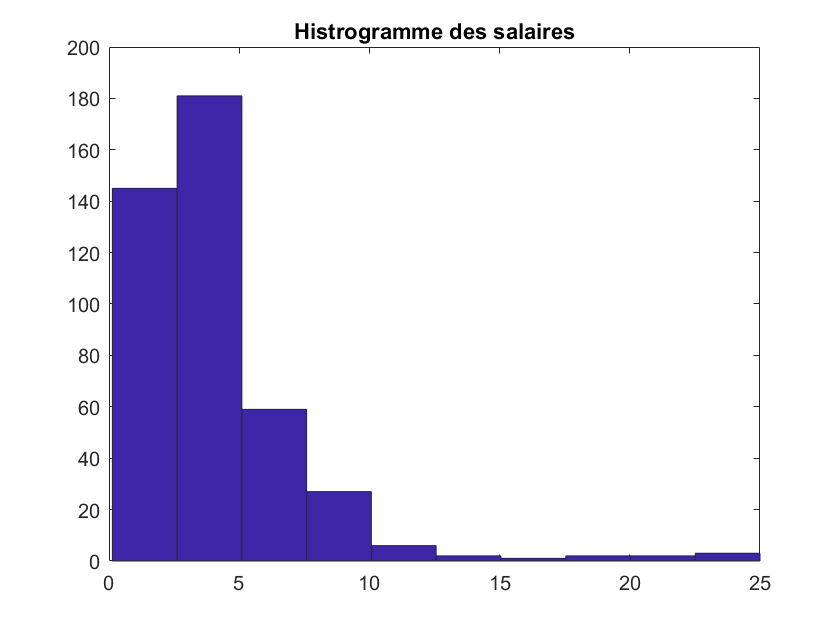

title('Histrogramme des salaires');

## Histogramme du logarithme des salaires

logwage = MROZ(:,21);
hist(logwage)
varlw = var(logwage)

varlw = 0.5230

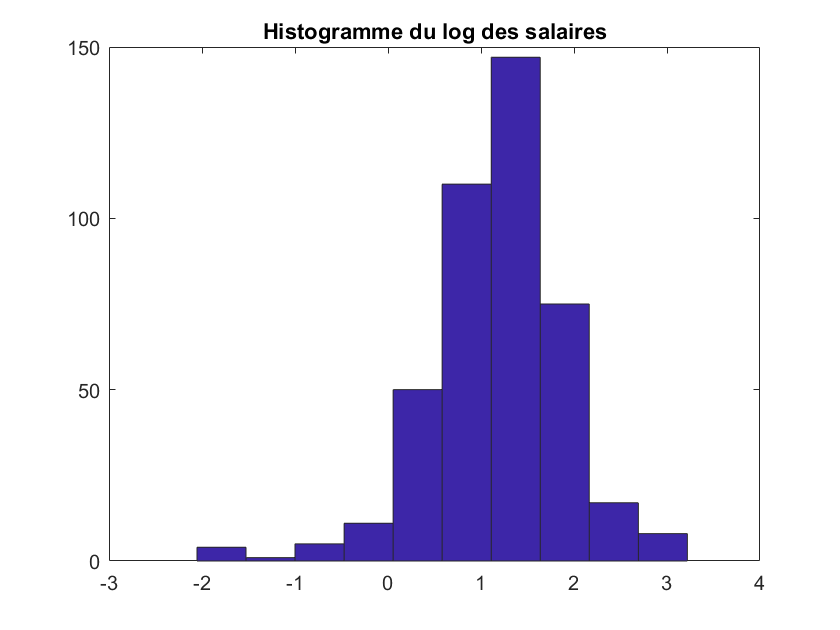

title('Histogramme du log des salaires');

## Interprétation : 

La répartition des salaires ne permet pas de conclure quant à la loi suivie par les salaires.

Par contre, la répartition des salaires montre que leur logarithme a tendance a suivre une loi normale centrée en 1,  mais pourtant pas réduite car la variance n'est pas égale à 1. 

# Question 4 : Calcul de corrélations

## Corrélation entre temps de scolarisation des mères et leur salaire

corMotheduc = corrcoef(MROZ(:,7),MROZ(:,15))

corMotheduc =     1.0000    0.0571
    0.0571    1.0000


## Corrélation entre temps de scolarisation des pères et leur salaire

corFatheduc = corrcoef(MROZ(:,7),MROZ(:,16))

corFatheduc =     1.0000    0.1077
    0.1077    1.0000


## Multicolinarité

corMothFath = corrcoef(MROZ(:,15),MROZ(:,16))

corMothFath =     1.0000    0.5541
    0.5541    1.0000


## Interprétation

On remarque qu'il y a une forte corrélation entre les variables Motheduc et Fatheduc. De plus, on remarque que le temps de scolarisation des pères a l'air d'avoir un peu plus d'impact sur leur salaire que le temps de scolarisation des mères sur leur salaire.

# Question 5 : Graphique en nuage de points

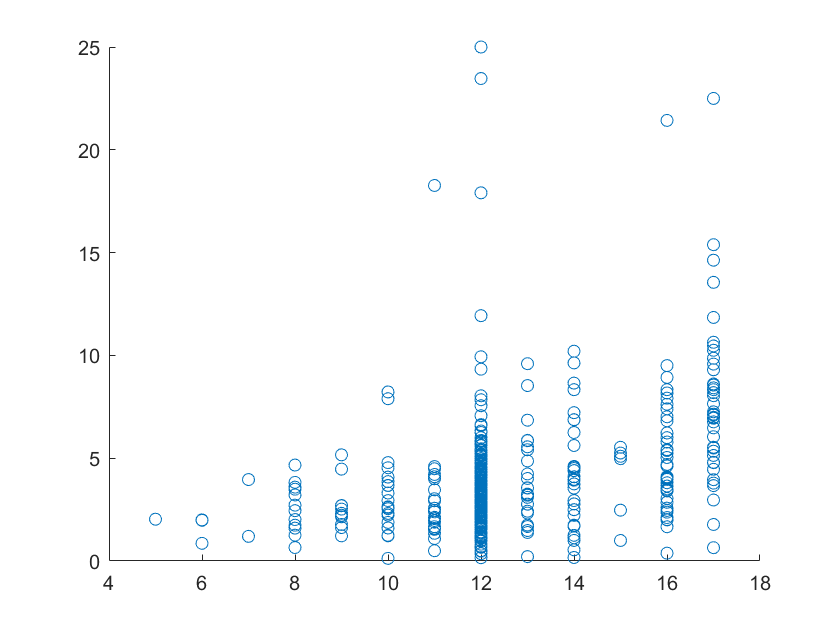

exper = MROZ(:,19);
fatheduc = MROZ(:,16);
scatter(educ,wage);

On obeserve une corrélation linéaire positive : plus la durée d'éducation grandit, plus le salaire augmente. En revanche, il y a une plus forte disparité des salaires. Il y a certains secteurs dans lesquels le salaire augmente plus que dans d'autres.

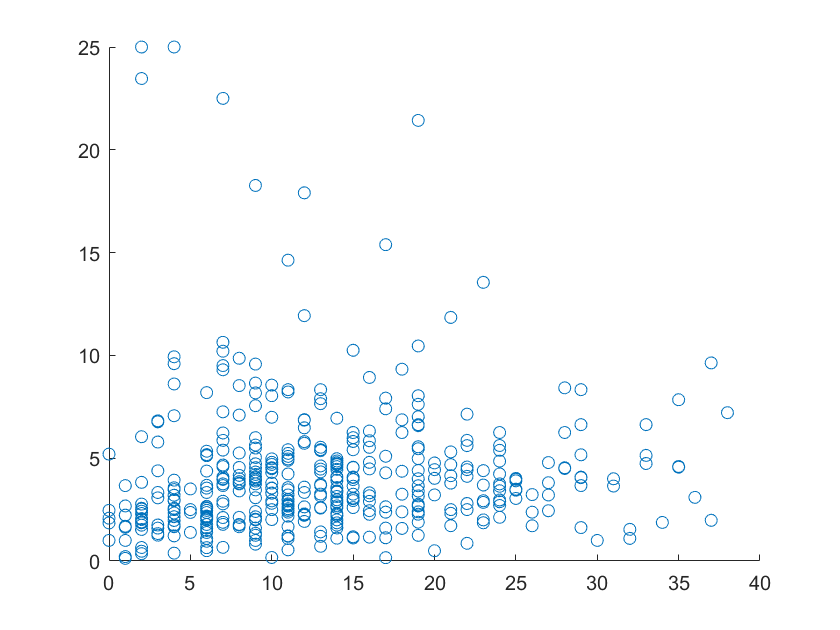

scatter(exper,wage);

C'est moins évident ici ! On observe qu'il y a une légère tendance à la hausse des salaires avec les années d'expérience, surtout de 0 à 20 ans. Au delà de 20 ans, ne peut donc rien conclure. On remarque de très haut salaires pour très peu d'expérience par ailleurs. 

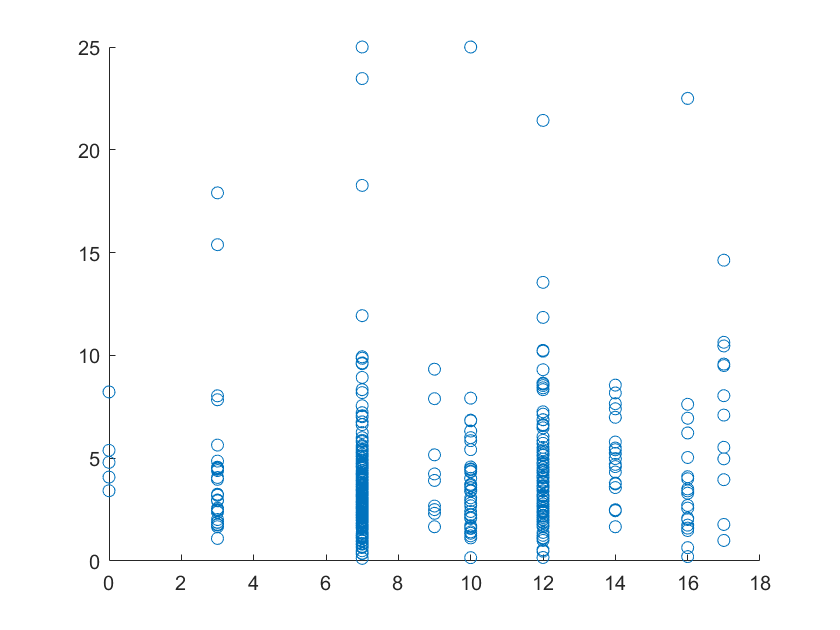

scatter(fatheduc,wage);

On ne peut rien conclure qur ce graphique.

Les femmes interrogées travaillent dans des secteurs différents, ont des métiers différents, où les salaires ne sont pas les mêmes. Ici, on ne peut pas dire "toutes choses sont égales par ailleurs" car les autres variables varient.

# Question 6 : Hypothèse fondamentale garantissant des estimateurs non biasés.

L'hypothèse fondamentale implique que les variables ne sont pas corrélées avec les résidus. autrement dit, E(u|X) = E(u) = 0, u étant le vecteur des résidus et X les variables.

Le biais de variable omise intervient lorsqu'il existe une variable corrélée aux autres variables et avec la donnée étudiée, mais que l'on ne dispose pas d'informations dessus, généralement parce qu'on ne peut pas la mesurer.

# Question 7 : Regression de wage en utilisant les variables explicatives city, educ, exper, nwifeinc, kidslt6, kidgt6 et une constante.

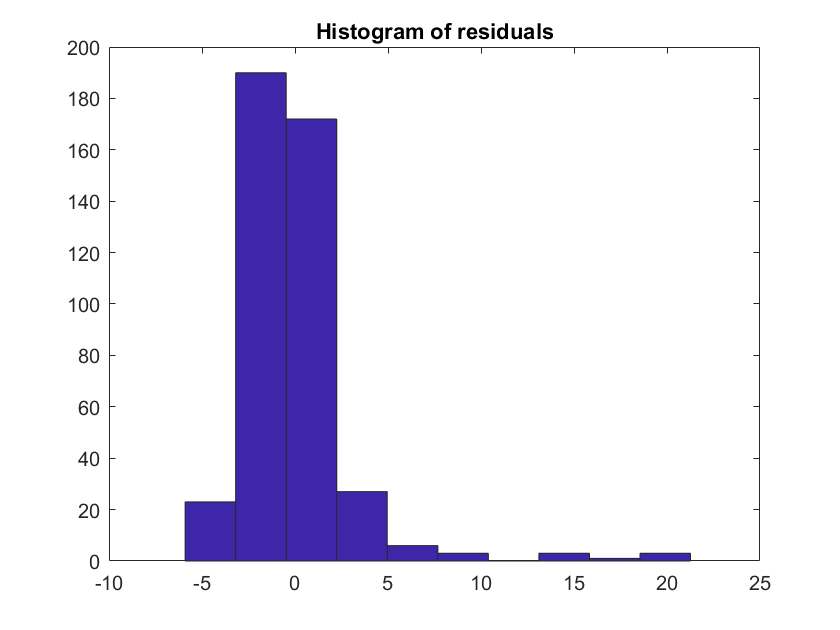

wage = MROZ(:,7);
[n, k] = size(wage);
X = [ones(n,1), MROZ(:,[18,6,19, 20, 3, 4])];%Création d'une variable X qui pendre en compte les différentes variables city, ... kidsgtl6.
[n,k] = size(X);
XT = transpose(X);
beta = inv(XT * X) * XT * wage; %calcul de coefficient en utilisant OLS
U = wage - X*beta; %calcul des résidus
hist(U)
title('Histogram of residuals');

variance_residus = var(U)

variance_residus = 9.5640

## Interprétation:

La variance est très grande et l'histogramme est dissymétrique donc on en pas assimiler les résidus à une loi normale centrée et réduite en 0. 

# Question 8 : Régression linéaire avec logwage

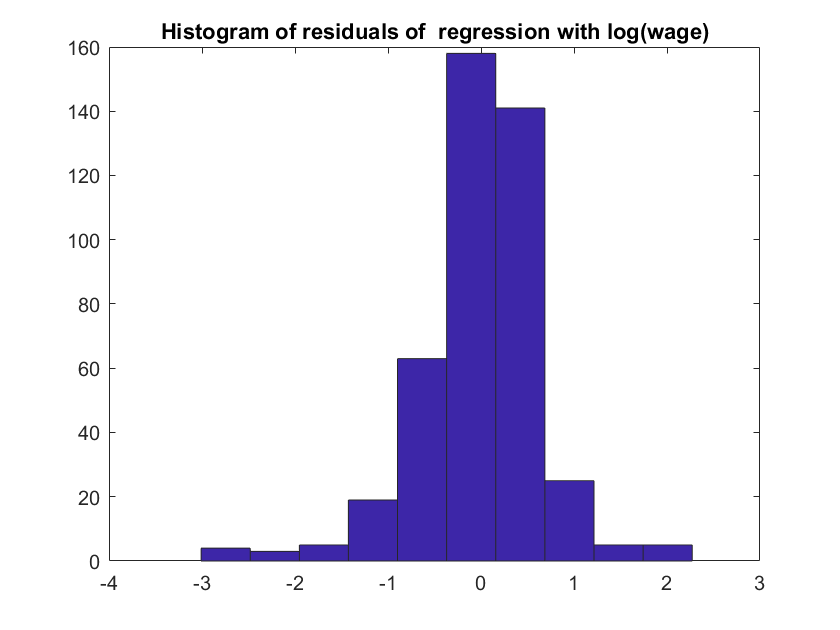

logwage = MROZ(:,21);
beta1 = inv(XT * X)* XT * logwage; %calcul du coefficient avec OLS
U1 = logwage - X * beta1; %calcul des résidus
hist(U1)
title('Histogram of residuals of  regression with log(wage)');

sig2=U1'*U1/(n-k);
stud=sqrt(diag(sig2*inv(X'*X)));
variances_residus_log = var(U1)

variances_residus_log = 0.4417

## Interprétation

La variance en utilisant le logarithme des salaires est de 0.44, donc bien plus faible que précédemment et plus proche de 1. De plus, l'histogramme est plus symétrique et centré en 0. Donc travailler avec des logarithmes permet d'avoir des résidus qui tendent plus vers une loi gaussienne centrée réduite, que sans logarithme.

# Question 9 : Test de l'hypothèse de non-significativité aux seuils 1%, 5% et 10%.

### Test de Student. 

t=beta1./stud;
%la variable nwifeinc est la 5e variable dans X, donc : 
disp(['Statistique de test = ' , num2str(t(5))])

Statistique de test = 1.466


disp(['tdis = ', num2str(1-tpdf(1.466, n-k))])

tdis = 0.86384


**La p-value de ce test est de 0,86384. **

disp(['tdis = ', num2str(tinv(0.99, n-k))])

tdis = 2.3352


On a $t = 1.466 < t_{99%} = 2.3352$ $ $= 2.3352$, donc on ne peut pas rejeter l'hypothèse $H_0$ à 1%. 

disp(['tdis = ', num2str(tinv(0.95, n-k))])

tdis = 1.6485


On a $t = 1.466 < t_{95%} = 2.3352$ $ $= 1.6485$, donc on ne peut pas rejeter l'hypothèse $H_0$ à 5%. 

disp(['tdis = ', num2str(tinv(0.90, n-k))])

tdis = 1.2836


On a $t = 1.466 < t_{90%} = 2.3352$ $= 1.2836$, donc on peut rejeter l'hypothèse $H_0$ à 10%. 

# Question 10 : Test que $\beta_{nwifeinc} = 0.01$ avec seuil de significativité à 5%

Cela revient à tester l'hypothèse $\beta - 0.01 = 0$.

logwage = MROZ(:,21);
X = [ones(n,1), MROZ(:,[18,6,19, 20, 3, 4])];
[n,k]=size(X);
XT = transpose(X);
Beta = inv(XT * X) * XT * logwage;
u = logwage - X*Beta;
uT = transpose(u);
sig2=uT*u/(n-7); 
std10=sqrt(diag(sig2*inv(XT*X)));

t = (Beta-0.01)./std10;
t_stat = t(5) %Il s'agit du 5e paramètre car la variable nwifeinc(20) est en 5e position dans X

t_stat = -1.5364

tInv = tinv(0.95,n-k)

tInv = 1.6485

On ne rejette pas l'hypothèse $H_0$, car la valeur de la statistique $t_stat = -1.5364$ est inférieure à celle du quantile en valeur absolue $t_{inv} = 1.6485$.

# Question 11 : Test de l'hypothèse jointe

Test de $H_{0}$ : $\beta_{nwifeinc} = 0.01$ and $\beta_{city} = 0.05$. 

Estimation du modèle non contraint avec log(wage) et calcul de SSR0, qui est le même que celui de la question 8 : logwage.

X = [ones(n,1), MROZ(:,[18,6,19, 20, 3, 4])];
beta1 = inv(XT * X)* XT * logwage; %calcul du coefficient avec OLS
U1 = logwage - X * beta1; %calcul des résidus
SSR0_11 = transpose(U1) * U1

SSR0_11 = 188.5900

Le modèle contraint est :$wage = \beta_0 + 0,01nwifeinc + 0,05city + \beta_1educ+\beta_2exper+\beta_3kidslt6 + \beta_4kidsgt6$

Il y a 2 contraintes ici.

Cela revient à faire la regression avec comme output $wage - \beta_0 - 0,01nwifeinc - 0,05city $ et en enlevant les colonnes correspondant à nwifeinc et city dans X.

[n,k] = size(X);
Xcontraint = [ones(n,1), MROZ(:,[6,19,3,4])]; %On enlève les données contraintes
logwage_contraint = logwage - 0.01 * MROZ(:,20) - 0.05 * MROZ(:,18);
beta_contraint = inv(transpose(Xcontraint) * Xcontraint) * transpose(Xcontraint) * logwage_contraint;
U_contraint=  logwage_contraint - Xcontraint * beta_contraint;
SSR1_11 = transpose(U_contraint) * U_contraint

SSR1_11 = 189.7879

Test de Fisher : F = $\frac{SSR1 - SSR0}{SSR0}$$\frac{n-k}{2}$

Ici on a  k-1 = 6, car le modèle non contraint dépend de 6 variables. Cependant, dans la formule du test de Fisher, on prend k = 7 car on a 7 variables qui entrent en compte dans le modèle non contraint (6 variables + l'intercept).

F_test = (SSR1_11- SSR0_11)*(n-k)/(SSR0_11* 2)

F_test = 1.3371

Finv = finv(0.95, 2, n-k)

Finv = 3.0172

Ici $F \lt F_{2,n-k}
$ donc on ne rejette pas $H_0
$

# Question 12 : Représentation graphique de l'impact de l'éducation et de l'expérience sur le salaire

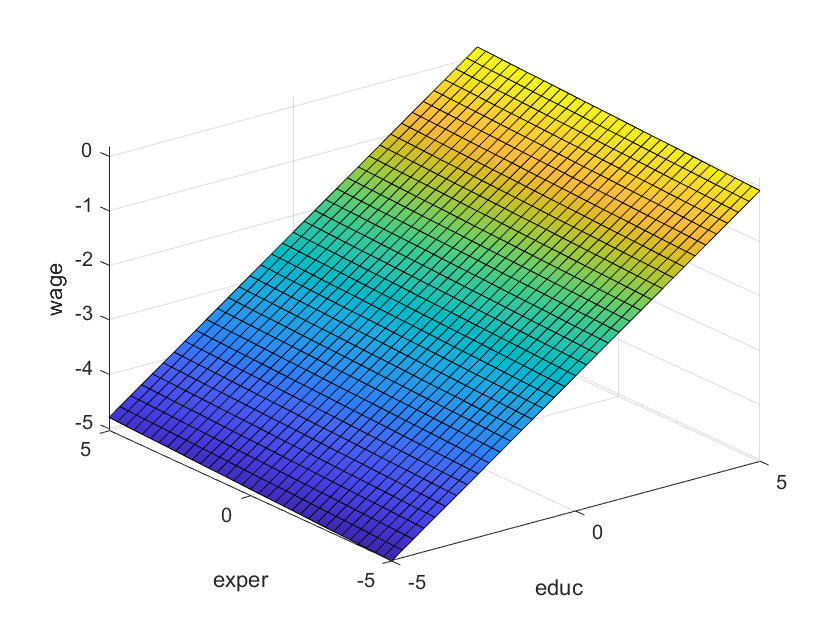

X12 = [ones(n,1), MROZ(:,[6,19])];

X12T = transpose(X12);
Beta12 = inv(X12T * X12) * X12T * wage;
fsurf(@(x,y) Beta12(2)*x + Beta12(1) + Beta12(3)*y)
xlabel('educ')
ylabel('exper')
zlabel('wage')

L'éducation a un plus gros impact que l'expérience sur le salaire. Cependant, on ne peut pas quantifier précisément cet impact car on ne sait pas ce que les échelles représentent exactement.

# Question 13 : Test de l'égalité des coefficients associé à kidsgt6 et kidslt6

logwage = MROZ(:,21);
[n,k]=size(MROZ);

## Construction de la variable de test

totcoll = MROZ(:,3) + MROZ(:,4);

## Regression de log(wage) sur les variables city (18) , educ (6), exper (19), nwifeinc (20), kidsgt6 (4) et kidslt6 (3)

X=[ones(n,1),MROZ(:,[6,18,19,20]),totcoll];
[n,k]=size(X);
beta=inv(transpose(X)*X)*transpose(X)*logwage;
u=logwage-X*beta;
sig2=u'*u/(n-k);
stud=sqrt(diag(sig2*inv(transpose(X)*X)));

## Test de Student

Le test de student revient à tester les hypothèses : 


$$H_{0} : \beta (kidsgt6 + kidslt6) = 0$$



$$H_1 : \beta (kidsgt6 + kidslit6) \neq 0$$


t = beta./stud;

La statistique de test pour $\beta (kidsgt6) - \beta (kidslt6)$ est : 

stat = t(6);
student = tinv(0.95,n-k-1);
fprintf('Statistique de test : %d\n0,95 percentile : %d',stat,student)

Statistique de test : -5.919864e-01
0,95 percentile : 1.648481e+00

**Donc on ne rejette pas l'hypothèse **$H_0$ **car en valeur absolue, la statistique est inférieure au 95% percentile. On peut considérer ce coefficient comme nul !**

# Question 14 : Homoscédaticité

On applique la formule du cours qui revient à tester la nullité des coefficients de la régression des carrés des résidus issus de la régression initiale. On utilise pour cela un test de Fisher !

Dans ce cas, le modèle contraint a 6 contraintes, et on a k=7.

X14=[ones(n,1),MROZ(:,[3,4,6,18,19,20])];
[n,k] = size(X14);
beta14=inv(X14'*X14)*X14'*wage;
u14=wage-X14*beta14;
y14 = u14.^2;
betawc = inv(X14'*X14)*X14'*y14;
betac = inv(ones(n,1)'*ones(n,1))*ones(n,1)'*y14;
u0 = y14 - X14*betawc;
u1 = y14 - ones(n,1)*betac;

SSR0 = u0'*u0;
SSR1 = u1'*u1;
F = ((SSR1 - SSR0)/SSR0)*(n-k)/6

F = 1.5926

p_value14 = 1-fcdf(F,6,n-k)

p_value14 = 0.1477

Finv14 = finv(0.95,6,n-k)

Finv14 = 2.1201

**Interprétation : **

**La p value est assez basse pour rejeter H0 qui était l'hypothèse d'égalité des variances (de nullité des coefficients dans la décomposition de u2).**

On corrige l'hétéroscédaticité pour améliorer :

pred = exp(X14*beta14);

X14c=[ones(n,1)./sqrt(pred),MROZ(:,[3,4,6,18,19,20])./sqrt(pred)];
y14c = wage./sqrt(pred);
beta14c=inv(X14c'*X14c)*X14c'*y14c;
u14c=y14c-X14c*beta14c;
y14cc = u14c.^2;
betawcc = inv(X14c'*X14c)*X14c'*y14cc;
betacc = inv((ones(n,1)./sqrt(pred))'*(ones(n,1)./sqrt(pred)))*(ones(n,1)./sqrt(pred))'*y14cc;
u0c = y14cc - X14c*betawcc;
u1c = y14cc - (ones(n,1)./sqrt(pred))*betacc;

SSR0c = u0c'*u0c;
SSR1c = u1c'*u1c;
Fc = ((SSR1c - SSR0c)/SSR0c)*(n-k)/6

Fc = 1.1663

p_value14c = 1-fcdf(Fc,6,n-k)

p_value14c = 0.3233

**Interprétation : **

**La p-value augmente ! Donc cela signifie que la probabilité de rejeter **$H_0$ **diminue :  on a donc bien corrigé l'hétéroscédaticité.**

# Question 15 : Test de changment de structure sur l'âge

**Note : Nous avons décidé d'évaluer l'intercept à chaque fois, c'est pour cela qu'on a k=7 variables.**

## Avec 2 groupes :

Il faut d'abord séparer les données en 2 groupes pour effectuer 2 régressions. L'énoncé précise qu'il faut effectuer le test sur l'ensemble des coefficients de la question 8.

$H_0
$ : Les coefficients associés aux femmes de moins de 43 ans et aux femmes de plus de 43 ans sont les mêmes.

s43 = (MROZ(:,5)>43);
X_plus43 = X(s43,:);
X_moins43 = X(~s43,:);
logwage_moins43 = logwage(~s43);
logwage_plus43 = logwage(s43);

Les tableaux sont créés, on fait maintenant les 2 régressions :

beta_plus43 = inv(X_plus43'*X_plus43)*X_plus43'*logwage_plus43;
beta_moins43 = inv(X_moins43'*X_moins43)*X_moins43'*logwage_moins43;
u_plus43 = logwage_plus43 - X_plus43*beta_plus43;
u_moins43 = logwage_moins43 - X_moins43*beta_moins43;
SSR0_15 = u_plus43'*u_plus43 + u_moins43'*u_moins43

SSR0_15 = 186.2269

Ici le SSR avec contraintes (i.e les mêmes coefficients pour les deux groupes) correspond au SSR de la question 11 : la somme des carrés des résidus de la regression de base.

SSR1_15 = SSR0_11

SSR1_15 = 188.5900

Ici, il y a 14 variables (les 2 régressions) et 7 contraintes (égalités de chaque variable entre les 2 groupes).

F_15 = (SSR1_15-SSR0_15)*(n-14)/(7*SSR0_15)

F_15 = 0.7505

p_value15 = 1 - fcdf(F_15,7,n-14)

p_value15 = 0.6293

Finv = finv(0.95,7,n-14)

Finv = 2.0317

**Interprétation : **

**On a : **$p_{value}$ **est assez élevée, donc la probabilité de faire une erreur en rejetant **$H_0$ **n'est pas faible. Dans ce cas, il semble donc cohérent de ne pas rejeter l'hypothèse nulle, donc on en déduit qu'il n'y a pas de changement de structure à 43 ans.**

## Avec 3 groupes :

On applique la même méthode mais avec 3 groupes (mutuellement exclusifs)

s30 = (MROZ(:,5)>30);
s3043 = logical(s30.*~s43);

X_moins30 = X(~s30,:);
X_entre3043 = X(s3043,:);

logwage_moins30 = logwage(~s30);
logwage_entre3043 = logwage(s3043);

beta_moins30 = inv(X_moins30'*X_moins30)*X_moins30'*logwage_moins30;
beta_entre3043 = inv(X_entre3043'*X_entre3043)*X_entre3043'*logwage_entre3043;

u_moins30 = logwage_moins30 - X_moins30*beta_moins30;
u_entre3043 = logwage_entre3043 - X_entre3043*beta_entre3043;

SSR0_15b = u_plus43'*u_plus43 + u_moins30'*u_moins30 + u_entre3043'*u_entre3043

SSR0_15b = 185.3117

On a 3*7 = 21 variables

On a 14 contraintes puisque pour chaque variable on a 2 égalités.

F_15b = (SSR1_15-SSR0_15b)*(n-21)/(14*SSR0_15b)

F_15b = 0.5143

p_value15b = 1 - fcdf(F_15b,14,n-21)

p_value15b = 0.9250

**Interprétation : **

**La **$p_{value}$**est très élevée, très proche de 1. On en déduit donc qu'on ne rejette donc pas H0 : il n'y a à priori pas de changement de structure entre ces 3 groupes.**

# Question 16 : Variables binaires

On a déjà créé des variables binaires à la question 15. Il suffit donc de les renommer pour plus de clareté :

under30 = ~s30; %30 ans inclus
between30and43 = s3043;
over43 = s43; %strictement

On enlève under30 pour la régression car c'est la référence. 

$H_0
$ : Les coefficients associés aux variables binaires sont nuls.

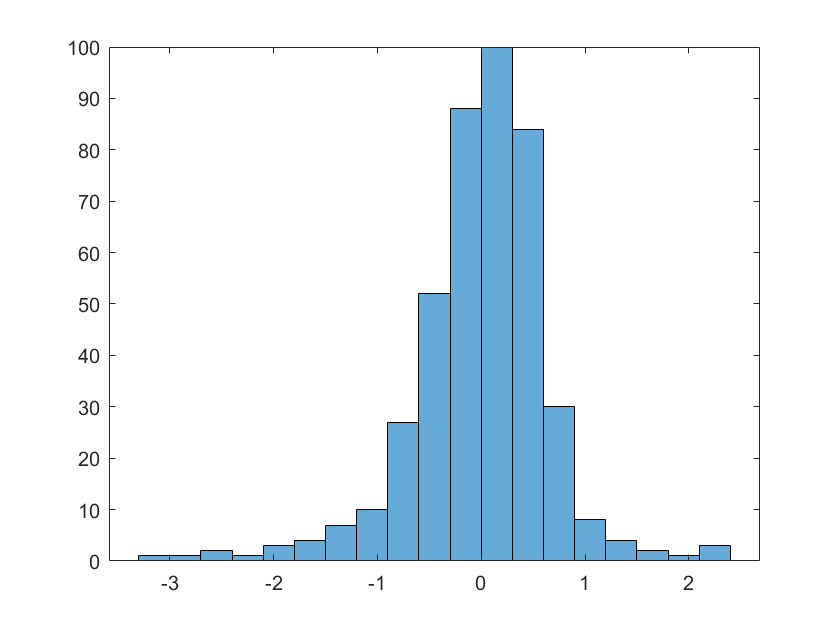

X_16 = [ones(n,1),MROZ(:,[3,4,6,18,19,20]),between30and43,over43];
beta_16 = inv(X_16'*X_16)*X_16'*logwage;
u_16 = logwage - X_16*beta_16;
histogram(u_16)

SSR0_16 = u_16'*u_16;

Le SSR avec contraintes (nullité des coefficients associés aux variables binaires) correspond au SSR sans contraintes qu'on a calculé à la question 11 (régression sans variable binaire).

SSR1_16 = SSR0_11;

Il y a 9 variables et 2 contraintes.

F_16 = (SSR1_16-SSR0_16)*(n-9)/(2*SSR0_16)

F_16 = 2.2139

Finv = finv(0.95,2,n-9)

Finv = 3.0173

p_value16 = 1 - fcdf(F_16,2,n-9)

p_value16 = 0.1105

**On a **$F < F_{6,n-9}$ **donc on ne rejette pas H0 :  les coefficients associés peuvent être considérés comme nuls. Cependant la p value est assez faible, donc l'erreur faite en rejetant l'hypothèse nulle est assez faible, donc la probabilité de rejeter l'hypothèse nulle reste assez forte.**